# How to programmatically configure a Simulink simulation?

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_06_20_WhatsThis/WhatsThis.prj)

Here is another frequently viewed MATLAB Answer post:

[Set simulation time and fixed step size for a Simulink model from the command line](https://www.mathworks.com/matlabcentral/answers/254468-set-simulation-time-and-fixed-step-size-for-a-simulink-model-from-the-command-line)

While this question asks specifically about stop time and solver step size, I think this can be generalized to this question: *How to find the programmatic equivalent of a block or model setting in Simulink?*

My answer to this is typically: Use **What's This?**

## Model Parameters

In case you never noticed, you can right-click on most configest parameters to see a "What's This?" menu being offered:

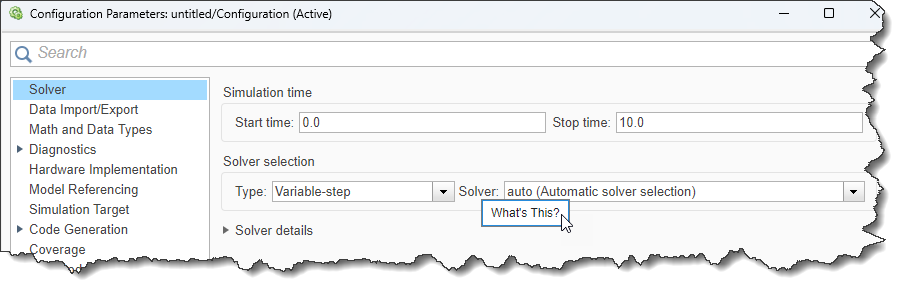

Clicking it opens a short descrition of the setting and the programmatic equivalent:

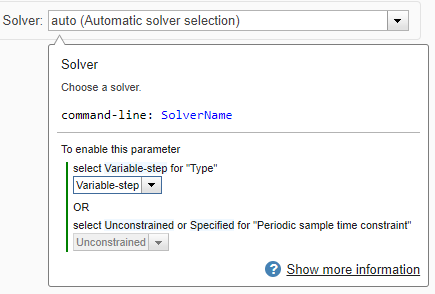

Clicking the Show more information link opens a seperate What's This Help window with more details:

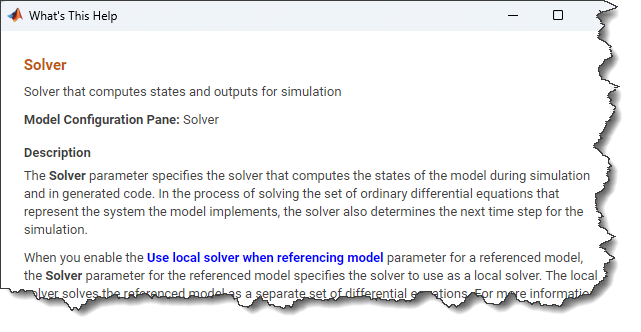

If you scroll toward the bottom, you will find a table listing everything you need to know about the programmatic use for this setting:

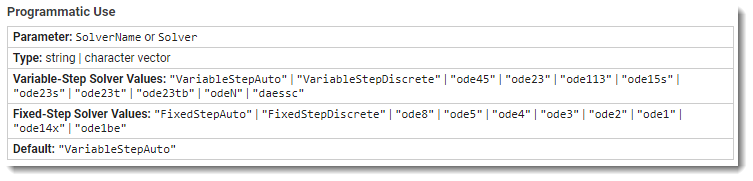

## Block Parameters

Most blocks parameters also have a What's This?:

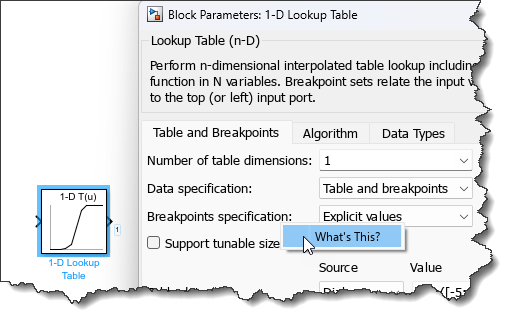

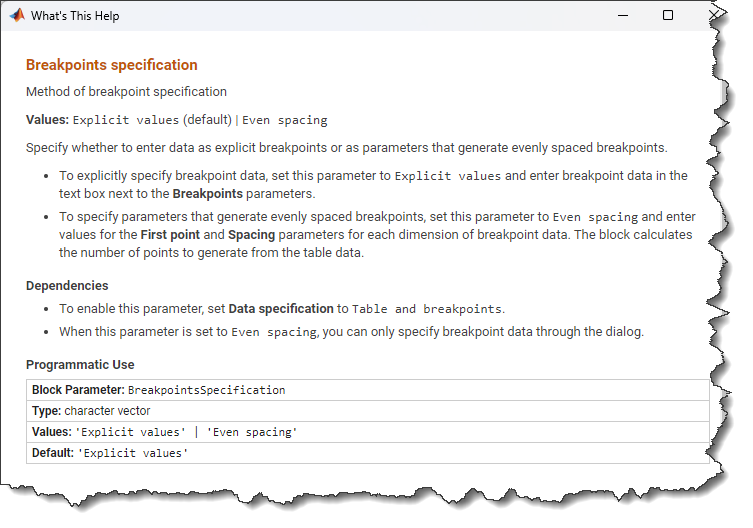

Now that we know how to obtain parameter names and possible values, let's see how to apply them.

## Simulating with different parameter values

In some cases, you want to simulate the modle with different parameter values, but not dirty or modify the model file. For that, I recommend using a Simulink.SimulationInput object. 

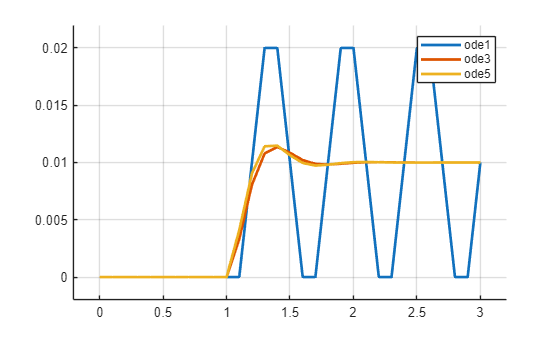

mdl = 'testStep';
solverChoices = {'ode1','ode3','ode5'};
N = length(solverChoices);
% Creating an array of Simulink.Simulationinput objects
in = repmat(Simulink.SimulationInput(mdl),N,1);
% specify different solvers for each simulation
in = arrayfun(@(i) in(i).setModelParameter('SolverName',solverChoices{i}),1:N);
out = sim(in,'ShowProgress','off');
% Plot results
figure; hold on;
arrayfun(@(i) plot(out(i).yout{1}.Values),1:N);
legend(solverChoices)

## Moddifying the model